robot = Robot();

time
        2000

acc time
   667

time
        2000

acc time
  666.6667



model = Model();
cam = Camera();

Clear surface of any items, then press any key to continue
Calibrating



			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Mapping coefficients:    [ 1628.5182 +/- 2.4350       -0.0004 +/- -0.0000       0.0000 +/- 0.0000       -0.0000 +/- -0.0000 ]
Distortion center (pixels):[  966.4776 +/- 1.1576      559.7080 +/- 1.1967  ]
Stretch matrix parameters:[    1.0000 +/- 0.0000        0.0000 +/- 0.0000        0.0000 +/- 0.0000  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.9518 +/- 0.0024        0.0579 +/- 0.0021        0.1246 +/- 0.0007  ]
                         [   -0.7491 +/- 0.0011       -0.0092 +/- 0.0011        0.1310 +/- 0.0004  ]
                         [    0.0924 +/- 0.0037       -0.0096 +/- 0.0020        0.0375 +/- 0.0002  ]
                         [   -0.7492 +/- 0.0011        0.6401 +/- 0.0011        1.4305 +/- 0.0005  ]
                         [   -0.5041 +/- 0.0014       -0.4725 +/- 0.0013       -1.5407 +/- 0.0004  ]
                        

World Points is 40 x 2
Image Points is 40 x 2
The checkerboard is 5 squares long x 11 squares wide


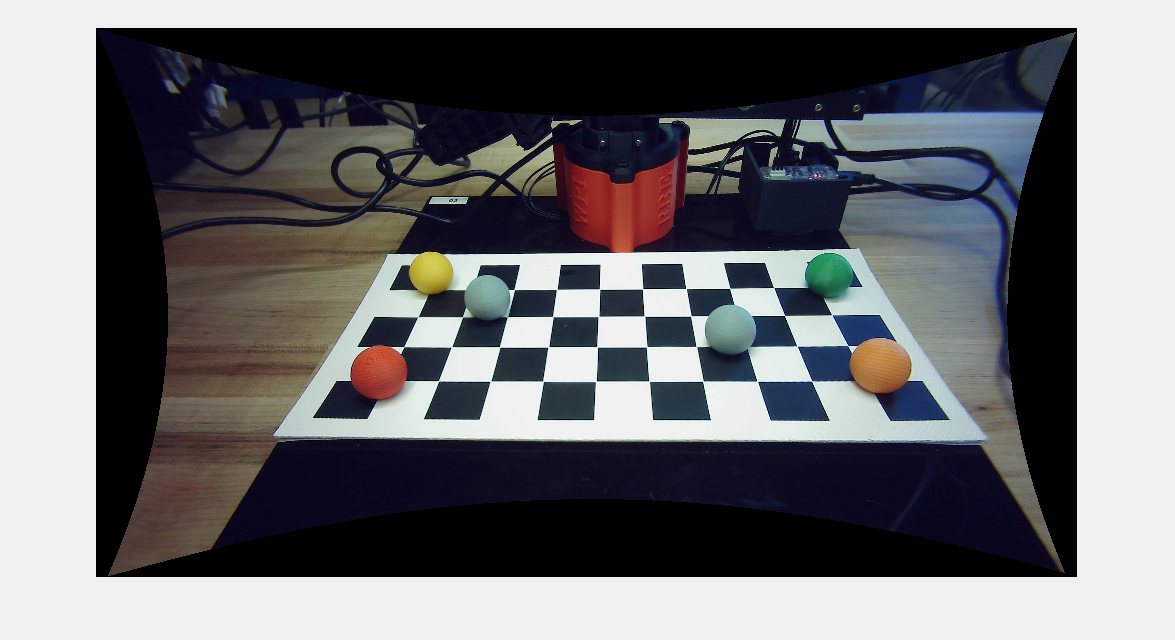

Put Ball On


k = 5

Average HSV for Circle 1: Hue = 0.12, Saturation = 0.68, Value = 0.65
Average RGB for Circle 1: R = 0.65, G = 0.54, B = 0.21
Average HSV for Circle 2: Hue = 0.15, Saturation = 0.67, Value = 0.72
Average RGB for Circle 2: R = 0.72, G = 0.67, B = 0.23
Average HSV for Circle 3: Hue = 0.46, Saturation = 0.25, Value = 0.57
Average RGB for Circle 3: R = 0.42, G = 0.57, B = 0.54
Average HSV for Circle 4: Hue = 0.43, Saturation = 0.71, Value = 0.51
Average RGB for Circle 4: R = 0.15, G = 0.51, B = 0.36
Average HSV for Circle 5: Hue = 0.10, Saturation = 0.59, Value = 0.67
Average RGB for Circle 5: R = 0.67, G = 0.51, B = 0.28


clickpoint = 1;
ptInterest = 1;
maskPts = [0, 0, 0, 0;
           0, 0, 0, 0];
try
    
  image = cam.getImage();
% image = imread("ALLCOLORS2.png");

imshow(image);
[x, y] = ginput(4);
maskPts = [x'; y'];
 try
          disp("Put Ball On");
          pause;      
 end
% while(1)
 image = cam.getImage();
[overlayImage, circleData] = cam.maskImageFunc(image, maskPts);
figure(2);
imshow(image);

% end

catch exception
    getReport(exception)
    disp('Exited on error, clean shutdown');
end